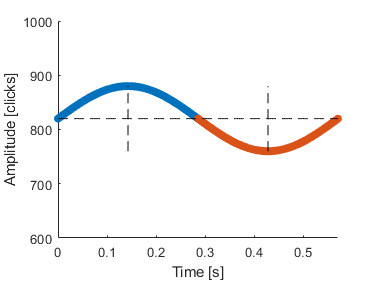

close all
clc
clear all

t_animation = 0.05:0.05:10;

%Animating amplitude
A_range = [60 140];
offset_range = [820 820];
phi_range = [0 0];
f_right_range = [1.75 1.75];
f_left_range = [1.75 1.75];

animateSinusoid(t_animation,A_range,offset_range,phi_range,f_right_range,f_left_range,'amplitude_animation');

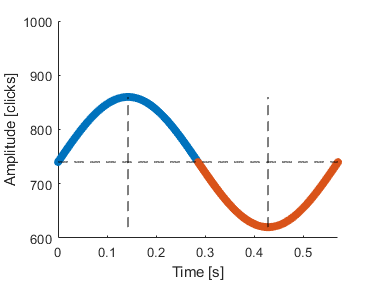

%Animating bias
A_range = [120 120];
offset_range = [740 900];
phi_range = [0 0];
f_right_range = [1.75 1.75];
f_left_range = [1.75 1.75];

animateSinusoid(t_animation,A_range,offset_range,phi_range,f_right_range,f_left_range,'bias_animation');

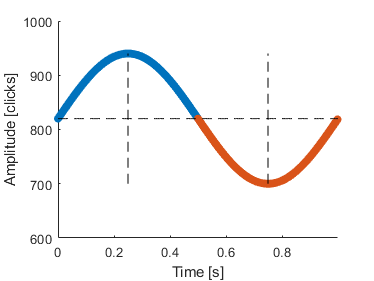

%Animating frequency
A_range = [120 120];
offset_range = [820 820];
phi_range = [0 0];
f_right_range = [1 3];
f_left_range = [1 3];

animateSinusoid(t_animation,A_range,offset_range,phi_range,f_right_range,f_left_range,'frequency_animation');

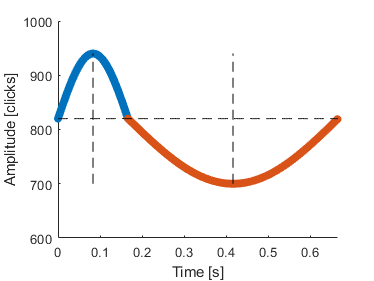


%Animating frequency difference
A_range = [120 120];
offset_range = [820 820];
phi_range = [0 0];
f_right_range = [1 3];
f_left_range = [3 1];

animateSinusoid(t_animation,A_range,offset_range,phi_range,f_right_range,f_left_range,'frequency_difference_animation');

function animateSinusoid(t_animation,A_range,offset_range,phi_range,f_right_range,f_left_range,filename)

%Creating ranges of parameter values based on animation time
A_vals = [linspace(A_range(1),A_range(2),length(t_animation)/2),linspace(A_range(2),A_range(1),length(t_animation)/2)];
offset_vals = [linspace(offset_range(1),offset_range(2),length(t_animation)/2),linspace(offset_range(2),offset_range(1),length(t_animation)/2)];
phi_vals = [linspace(phi_range(1),phi_range(2),length(t_animation)/2),linspace(phi_range(2),phi_range(1),length(t_animation)/2)];

f_left_vals = [linspace(f_right_range(1),f_right_range(2),length(t_animation)/2),linspace(f_right_range(2),f_right_range(1),length(t_animation)/2)];
f_right_vals = [linspace(f_left_range(1),f_left_range(2),length(t_animation)/2),linspace(f_left_range(2),f_left_range(1),length(t_animation)/2)];
p_right_vals = 1./f_right_vals; %Period of right leg input in [s]
p_left_vals = 1./f_left_vals; %Period of left leg input in [s]

t = zeros(length(t_animation),10000); %time vector for sinusoid


%Creating position vectors for sinusoid data for each iteration
pos_right_vals = zeros(length(t_animation),10000);
pos_left_vals = zeros(length(t_animation),10000);

t_right = zeros(length(t_animation),10000);
t_left = zeros(length(t_animation),10000);



for j = 1:length(t_animation)

    %Updating parameters for sinusoid
    A = A_vals(j);
    phi = phi_vals(j);
    offset = offset_vals(j);

    f_left = f_left_vals(j);
    f_right = f_right_vals(j);
    
    w_left = 2*pi*f_left;
    w_right = 2*pi*f_right;
    
    p_right = p_right_vals(j);
    p_left = p_left_vals(j);

    period_total = 1/(2*f_left)+1/(2*f_right); %Total period
    t(j,:) = linspace(0,period_total-0.0001,10000);



    %Calculating positions for each period
    for i = 1:length(t(j,:))
        tau = mod(t(j,i),period_total);

        %First half
        if (tau < p_right/2)
            pos_right_vals(j,i) = A.*sin(w_right.*t(j,i) + phi) + offset;
            t_right(j,i) = t(j,i);

        %Second half
        elseif (p_right/2 <= tau)&&(tau <= p_right/2 + p_left/2)
            pos_left_vals(j,i) = A.*sin(w_left.*(t(j,i) - p_right/2 + p_left/2) + phi) + offset;
            t_left(j,i) = t(j,i);
        
        end

    end

end

%%%%%%%%%%%%%%%%%%%%%
%%Animating sinusoid
%%%%%%%%%%%%%%%%%%%%%%


%Getting rid of zeros in left position vector
% t_right = t_right(:,pos_right_vals(1,:)~=0);
% t_left = t_left(:,pos_left_vals(1,:)~=0);
% pos_right_vals = pos_right_vals(:,pos_right_vals(1,:)~=0);
% pos_left_vals = pos_left_vals(:,pos_left_vals(1,:)~=0);



%Initial plot of sinusoid
figure();
hold on;
hR = scatter(t_right(1,:),pos_right_vals(1,:),'filled');
hL = scatter(t_left(1,:),pos_left_vals(1,:),'filled');
hPMarker1 = plot((p_right_vals(1)/4).*ones(1,100),linspace(offset_vals(1)-A_vals(1),offset_vals(1)+A_vals(1),100),'--k');
hPMarker2 = plot((p_right_vals(1)/4+p_left_vals(1)/2).*ones(1,100),linspace(offset_vals(1)-A_vals(1),offset_vals(1)+A_vals(1),100),'--k');

plot(t(1,:),offset_vals(1).*ones(1,length(t(1,:))),'--k'); %X-axis

xlabel('Time [s]');
ylabel('Amplitude [clicks]');
axis([t(1,1) t(1,end) 600 1000]);
hold off;

% vid = VideoWriter(filename);
% vid.FrameRate = 60;
% vid.Quality = 98;
% open(vid);

for i = 1:length(t_animation)

    tic

    t_right_curr = t_right(i,pos_right_vals(i,:)>0);
    t_left_curr = t_left(i,pos_left_vals(i,:)>0);
    pos_right_curr = pos_right_vals(i,pos_right_vals(i,:)>0);
    pos_left_curr = pos_left_vals(i,pos_left_vals(i,:)>0);


    %Updating plot data
    hR.XData = t_right_curr;
    hR.YData = pos_right_curr;
    hL.XData = t_left_curr;
    hL.YData = pos_left_curr;

    hPMarker1.XData = (p_right_vals(i)/4).*ones(1,100);
    hPMarker2.XData = (p_right_vals(i)/2+p_left_vals(i)/4).*ones(1,100);

    axis([t(i,1) t(i,end) 600 1000]);

    %Updating animation
    dt_animation = toc();
    waittime = 0.01;
    if dt_animation<waittime
        pause(waittime-dt_animation)
        %frame = getframe(gcf);
        %writeVideo(vid,frame);
    end

end

%close(vid);

end
